# Visualizations

## set up environment

close all;
clear;
clc;

temp = csvread('gnss-1.csv', 1, 0);
gnss1.t = temp(:, 1);
gnss1.x = temp(:, 2);
gnss1.y = temp(:, 3);

temp = csvread('groundtruth-1.csv', 1, 0);
true.t = temp(:, 1);
true.x = temp(:, 2);
true.y = temp(:, 3);
true.phi = temp(:, 4);

temp = csvread('wheelspeeds-1.csv', 1, 0);
ws.t = temp(:, 1);
ws.vr = temp(:, 2);
ws.vl = temp(:, 3);

clear temp


## Computations

R = 0.27;

v = (ws.vr + ws.vl) / 2;
phi_dot = (ws.vr - ws.vl) / (2*R);

ti = ws.t(1:end-1);
tf = ws.t(2:end);
dt = [0; tf - ti];

phi = cumsum(phi_dot .* dt);
vx = v .* cos(phi);
vy = v .* sin(phi);
x = cumsum(vx .* dt);
y = cumsum(vy .* dt);


## Plotting

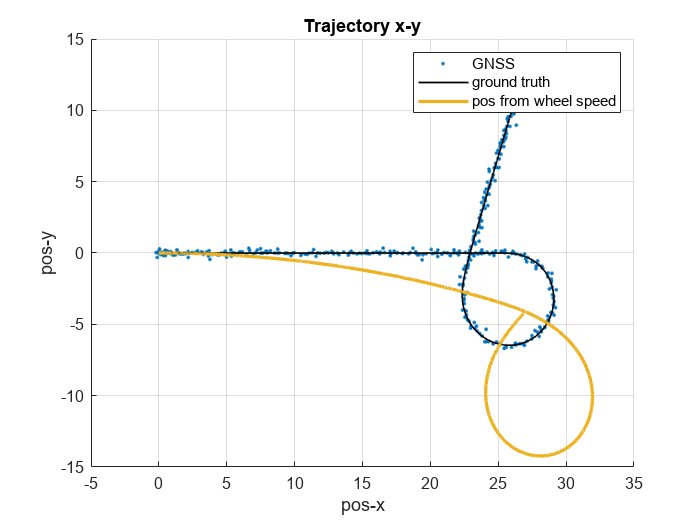

figure();
hold on;
plot(gnss1.x, gnss1.y, '.', 'DisplayName', 'GNSS');
plot(true.x, true.y, 'LineWidth', 1, 'DisplayName', 'ground truth', 'Color', 'k');
plot(x, y, 'LineWidth', 2, 'DisplayName', 'pos from wheel speed');
legend();
xlabel('pos-x')
ylabel('pos-y')
title("Trajectory x-y");
hold off;
grid on;

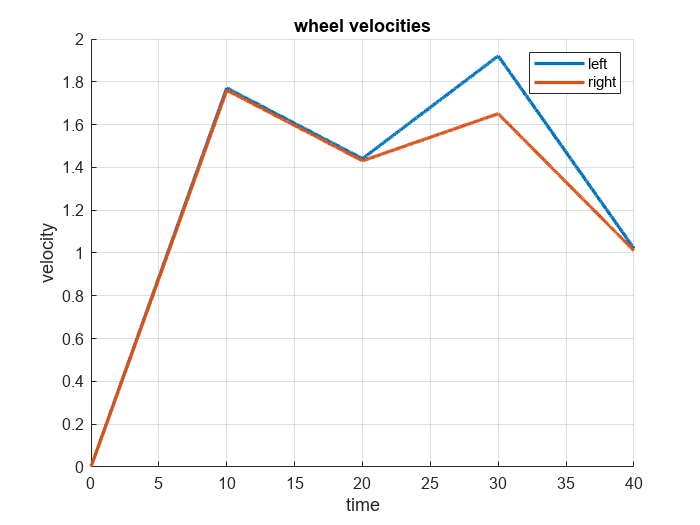


figure();
hold on;
plot(ws.t, ws.vl, 'LineWidth', 2, 'DisplayName', 'left');
plot(ws.t, ws.vr, 'LineWidth', 2, 'DisplayName', 'right');
legend();
xlabel('time')
ylabel('velocity')
title("wheel velocities");
hold off;
grid on;